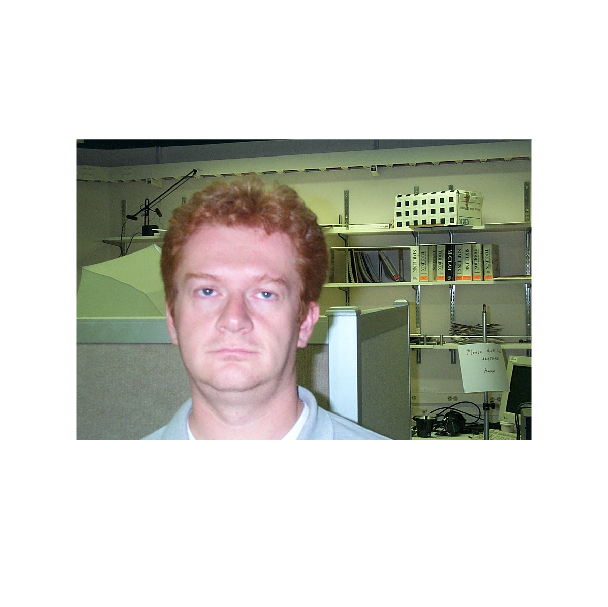

clear
realId = 2; 

% Se till att du är i "/GitHub/TNM034_Projekt" när du läser in 
%image = imread("./Faces/db1_" + realId + ".jpg");
%image = imread("./Faces/db0_" + realId + ".jpg");
%image = imread("./Faces/DB2/il_" + realId + ".jpg");
%image = imread("./Faces/DB2/cl_" + realId + ".jpg");
%image = imread("./Faces/DB2/ex_" + realId + ".jpg");
image = imread("./Faces/DB2/bl_" + realId + ".jpg");

image = im2double(image);
imshow(image)

id = tnm034(image)

Error in findEyesUsingCircularHough: Index in position 1 exceeds array bounds.

From getFaceId:

Distance id 1: 8.243e-02
Distance id 2: 1.097e-01
Distance id 3: 1.033e-01
Distance id 4: 1.620e-01
Distance id 5: 1.520e-01
Distance id 6: 1.493e-01
Distance id 7: 7.128e-02
Distance id 8: 2.086e-01
Distance id 9: 1.389e-01
Distance id 10: 9.935e-02
Distance id 11: 7.336e-02
Distance id 12: 6.193e-02
Distance id 13: 1.015e-01
Distance id 14: 1.070e-01
Distance id 15: 1.177e-01
Distance id 16: 8.913e-02

Closest id: 12


id = 12


if id == realId
    fprintf('Correct id!')
else
    fprintf('Not correct id :/')
end   

Not correct id :/

## Tetst All Images

%clear all
% Load face images from a folder
imageDir = 'Faces/';
imageDir2 = 'Faces/DB2/';
testimages = dir(fullfile(imageDir, '*.jpg'));
testimages2 = dir(fullfile(imageDir2, '*.jpg'));
allImages = [testimages; testimages2];
numImages = numel(allImages);

% Read images into a cell array
faceData = cell(1, numImages);
classIds = zeros(1, numImages);
for i = 1:numImages
    % Load your image
    image = im2double(imread(fullfile(allImages(i).folder, allImages(i).name)));
    %imshow(image)
    id = tnm034(image)
    fprintf('Correct id: %i',number(allImages(i).name));
    pause(0.1)
end

imCorrected = imCorrected(:,:,1) =

    0.8431    0.8471    0.8471    0.8431    0.8392    0.8431    0.8431    0.8353    0.8353    0.8471    0.8510    0.8431    0.8353    0.8431    0.8471    0.8431    0.8196    0.8275    0.8431    0.8353    0.8431    0.8510    0.8471    0.8667    0.8588    0.8549    0.8471    0.8471    0.8314    0.8118    0.8314    0.8510    0.8706    0.8549    0.8549    0.8667    0.8784    0.9255    0.9490    0.9725    0.9765    0.9843    0.9686    0.9608    0.9529    0.9333    0.9059    0.8745    0.8824    0.8706    0.8824    0.8902    0.8941    0.8549    0.8941    0.7961    0.7176    0.8392    0.8824    0.8667    0.8118    0.7216    0.8000    0.8039    0.8667    0.7843    0.6588    0.7059    0.7569    0.8549    0.8784    0.8627    0.8588    0.8471    0.8784    0.8824    0.7686    0.8078    0.8784    0.8588    0.8706    0.8824    0.8706    0.8706    0.9137    0.9294    0.9216    0.8941    0.8627    0.8471    0.8353    0.8667    0.8471    0.8667    0.8431    0.8275    

Error using chromadapt>parseInputs
Expected ColorSpace to match one of these values:

'srgb', 'adobe-rgb-1998', 'linear-rgb'

The input, 'prophoto-rgb', did not match any of the valid values.

Error in chromadapt (line 154)
inputs = parseInputs(varargin{:});

Error in adjustRGB (lin